## Utilizziamo anche le features

## Caricamento dei dati

Vengono caricati i dati di training, validation e test set come image datastore. imageDatastore automaticamente applica le label alle classi in base ai nomi delle cartelle delle immagini e salva i dati come oggetti ImageDatastore.

% caricamento dei dati
imdsTrain = imageDatastore('dataset/TrainSet/','IncludeSubfolders',true,'LabelSource','foldernames');
imdsValidation = imageDatastore('dataset/ValSet','IncludeSubfolders',true,'LabelSource','foldernames');
imdsTest = imageDatastore('dataset/TestSet/','IncludeSubfolders',true,'LabelSource','foldernames');
%numero di dati caricati
numTrainImages = numel(imdsTrain.Labels)

numTrainImages = 162770

numValImages = numel(imdsValidation.Labels)

numValImages = 19867

numTestImages = numel(imdsTest.Labels)

numTestImages = 19962

## Analisi dei dati

Stampa casuale di alcune delle immagini appartenenti al training set

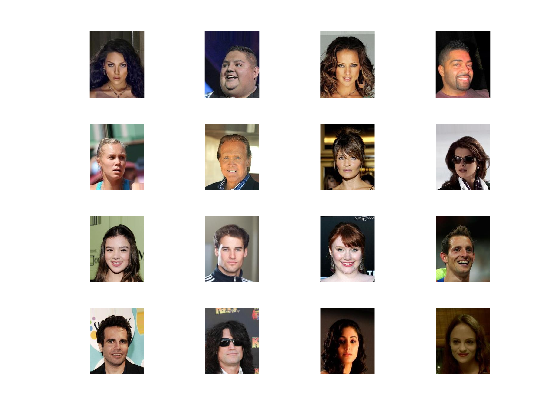

if printTrainingSet == 1
    idx = randperm(numTrainImages,16);
    figure
    for i = 1:16
        subplot(4,4,i)
        I = readimage(imdsTrain,idx(i)); %%%useremo questo per l'acquisizione delle immagini
        imshow(I)
    end
end

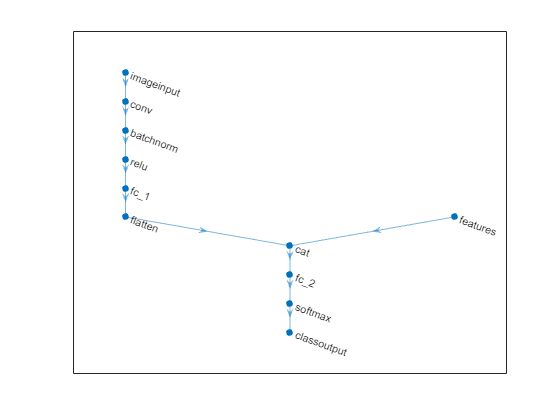




A = readmatrix('dataset/TrainSet_features.txt', 'Delimiter', ' ');
                                           



%https://it.mathworks.com/matlabcentral/answers/216671-read-txt-file-into-a-matrix
X2Train = A;
TTrain = imdsTrain.Labels;
X1Train = readall(imdsTrain);







dsX1Train = arrayDatastore(X1Train,IterationDimension=4);
dsX2Train = arrayDatastore(X2Train);
dsTTrain = arrayDatastore(TTrain);
dsTrain = combine(dsX1Train,dsX2Train,dsTTrain);









[h,w,numChannels,numObservations] = size(X1Train);
numFeatures = 39;
numClasses = numel(categories(TTrain));

imageInputSize = [h w numChannels];
filterSize = 40;
numFilters = 130;

layers = [
    imageInputLayer(imageInputSize,Normalization="none")
    convolution2dLayer(filterSize,numFilters)
    batchNormalizationLayer
    reluLayer
    fullyConnectedLayer(50)
    flattenLayer
    concatenationLayer(1,2,Name="cat")
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer];

lgraph = layerGraph(layers);










featInput = featureInputLayer(numFeatures,Name="features");
lgraph = addLayers(lgraph,featInput);
lgraph = connectLayers(lgraph,"features","cat/in2");

figure
plot(lgraph)





options = trainingOptions("sgdm", ...
    MaxEpochs=15, ...
    InitialLearnRate=0.01, ...
    Plots="training-progress", ...
    Verbose=0);

net = trainNetwork(dsTrain,lgraph,options);

Error using trainNetwork
Invalid network.

Caused by:
    Layer 'conv': The size of the convolution dimensions of the padded input data must be larger than or equal to the filter size. For networks with sequence input, this check depends on the MinLength property of
    the sequence input layer. To ensure that this check is accurate, set MinLength to the shortest sequence length of your training data.


%%%%% da modificare per il test cosi non buono
[X1Test,TTest,X2Test] = digitTest4DArrayData;
dsX1Test = arrayDatastore(X1Test,IterationDimension=4);
dsX2Test = arrayDatastore(X2Test);
dsTest = combine(dsX1Test,dsX2Test);


YTest = classify(net,dsTest);

Error using DAGNetwork/classify
Incorrect input size. The input images must have a size of [227 227 3].

Error in SeriesNetwork/classify (line 611)
            [labels, scores] = this.UnderlyingDAGNetwork.classify(X, varargin{:});


figure
confusionchart(TTest,YTest)

accuracy = mean(YTest == TTest)


idx = randperm(size(X1Test,4),9);
figure
tiledlayout(3,3)
for i = 1:9
    nexttile
    I = X1Test(:,:,:,idx(i));
    imshow(I)

    label = string(YTest(idx(i)));
    title("Predicted Label: " + label)
end